#    **Digital Communication Systems**

# **CA3**

***Reza Jahani / 810198377***

***---------------------------------------------------------------------------------***

##  Generation and Transmitting symbols using 4-PAM

First we start by generating the raised cosine pulse.

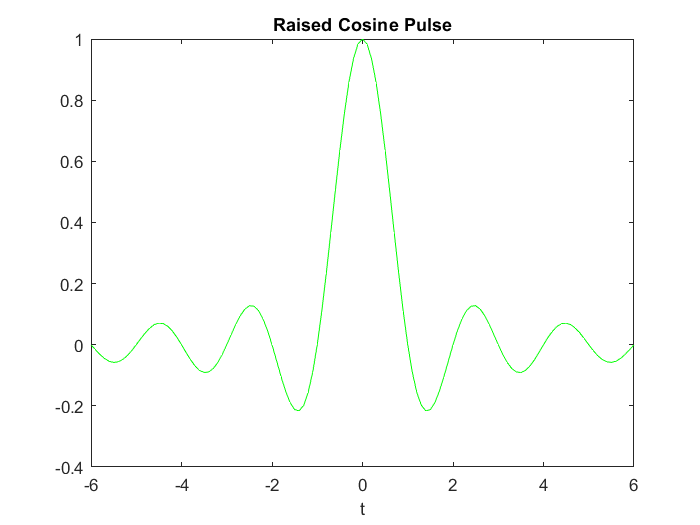

beta = 0;
sampling_error = 0;
[p,t] = RCP(sampling_error,beta);
figure(1);
plot(t,p,'g');
xlabel('t');
title('Raised Cosine Pulse');

Now we aim to generate a random sequence of symbols and then create the modulate symbols.

N = 10^6;
chain = rand(N,1);
symbols = chain;
symbols(symbols > 0 & symbols < 0.1) = 1;           %A
symbols(symbols >= 0.1 & symbols < 0.5) = 2;        %B
symbols(symbols >= 0.5 & symbols < 0.9) = 3;        %C
symbols(symbols >= 0.9 & symbols < 1) = 4;          %D
modulated_symbols = symbols;
modulated_symbols(modulated_symbols == 1) = -3;     %A
modulated_symbols(modulated_symbols == 2) = -1;     %B
modulated_symbols(modulated_symbols == 3) = 1;      %C
modulated_symbols(modulated_symbols == 4) = 3;      %D

Now that we want to generate the transmitted signal.

T = 1;
Fs = 10;
L = T*Fs;

signal = upsample(modulated_symbols,L);
signal = signal(1:end-(L-1));

transmitted_signal = conv(p,signal);

Noise generation and adding the noise to our transmitted signal.

snr_db = 0:10;
Es = 0.1*(-3)^2 + 0.4*(-1)^2 + 0.4*(1)^2 + 0.1*(3)^2;
received_signal = zeros(11,length(transmitted_signal));
etas = zeros(1,11);
for i=1:11
   snr = 10^(snr_db(i)/10);
   eta = Es/snr;
   etas(i) = eta;
   noise = randn(1,length(transmitted_signal));
   noise = sqrt(eta/2) * noise;
   noise = noise';
   received_signal(i,:) = transmitted_signal + noise;
end

## Symbol Detection using ML & MAP Receiver

- Sampling

T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples = received_signal(:,T_sampling);

- Threshold Calculations

#### ML Receiver:

We already know that ML receiver does not depend on the probability of transmitted symbols.


$$\Delta_L =\frac{A^{\left(L+1\right)} +A^{\left(L\right)} }{2}\;\;\;$$


This way our threshold will be exactly in the middle of modulation points resulting in:


$$\Delta_1 =-2$$
       
$$\Delta_2 =0$$
       
$$\Delta_3 =2$$


#### MAP Receiver:    

In MAP receiver, thresholds are obtained by interception of $\psi_L \;$probability functions. Assuming the noise has distribution of $N\left(0,\frac{\eta }{2}\right)$ the interceptions will be gained as below. First we start by generating the $\psi_L \;$probability functions.


$$\psi_1 =0\ldotp 1\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y+3\right)}^2 }{\eta }}$$
 


$$\psi_2 =0\ldotp 4\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y+1\right)}^2 }{\eta }}$$



$$\psi_3 =0\ldotp 4\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y-1\right)}^2 }{\eta }}$$



$$\psi_4 =0\ldotp 1\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y-3\right)}^2 }{\eta }}$$


First Threshold)

$0\ldotp 1\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y+3\right)}^2 }{\eta }}$ = $0\ldotp 4\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y+1\right)}^2 }{\eta }}$    $\to \;-{\left(y+3\right)}^2 =\eta \ldotp \textrm{Ln}\left(4\right)-{\left(y+1\right)}^2 \;\;\;\to$        $\Delta_{1\;} =-\frac{1}{4}\left(\eta \ldotp \textrm{Ln}\left(4\right)+8\right)$

Second Threshold)


$$\psi_{2\;} \textrm{and}\;\psi_3 \;\textrm{are}\;\textrm{symmetric}\;\textrm{so}\;\textrm{the}\;\textrm{threshold}\;\textrm{would}\;\textrm{be}\;$$
    
$$\Delta_{2\;} =0$$


Third Threshold)

$0\ldotp 4\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y-1\right)}^2 }{\eta }}$= $0\ldotp 1\frac{1}{\sqrt{2\pi \sqrt{\frac{\eta }{2}}}}e^{-\frac{{\left(y-3\right)}^2 }{\eta }} \;\;\;\to \;\;\;\textrm{applying}\;\textrm{same}\;\textrm{actions}\;\textrm{like}\;\textrm{first}\;\textrm{threshold}\to$             $\Delta_{3\;} =\frac{1}{4}\left(\eta \ldotp \textrm{Ln}\left(4\right)+8\right)$

Based on calculations above thresholds are:


$$\Delta_{1\;} =-\frac{1}{4}\left(\eta \ldotp \textrm{Ln}\left(4\right)+8\right)$$
            
$$\Delta_{2\;} =0$$
        
$$\Delta_{3\;} =\frac{1}{4}\left(\eta \ldotp \textrm{Ln}\left(4\right)+8\right)$$


- Symbols Detection

%Thresholds
MLth = [-2 0 2];
MAPth = zeros(11,3);
MAPth(:,1) = -1/4*(etas*log(4) + 8);
MAPth(:,2) = 0;
MAPth(:,3) = +1/4*(etas*log(4) + 8);

%Decision and Detecting
detected_symbols_MAP = zeros(11,N);
detected_symbols_ML = zeros(11,N);
for i=1:11
   th_MAP = MAPth(i,:);
   th_ML = MLth;
   detected_symbols_MAP(i,:) = detect_symbols(samples(i,:),th_MAP);
   detected_symbols_ML(i,:) = detect_symbols(samples(i,:),th_ML);
end

Symbols are detected using the simple algorithm above.

- Error Calculation

error_MAP = zeros(1,11);
error_ML = zeros(1,11);
for i=1:11
    ds_MAP = detected_symbols_MAP(i,:);
    ds_MAP = ds_MAP';
    ds_ML = detected_symbols_ML(i,:);
    ds_ML = ds_ML';
    eq_MAP = (ds_MAP == modulated_symbols);
    eq_ML = (ds_ML == modulated_symbols);
    error_MAP(i) = N - sum(eq_MAP);
    error_ML(i) = N - sum(eq_ML);
end
Pe_MAP = error_MAP / N;
Pe_ML = error_ML / N;

- Error Probabilty Plot 

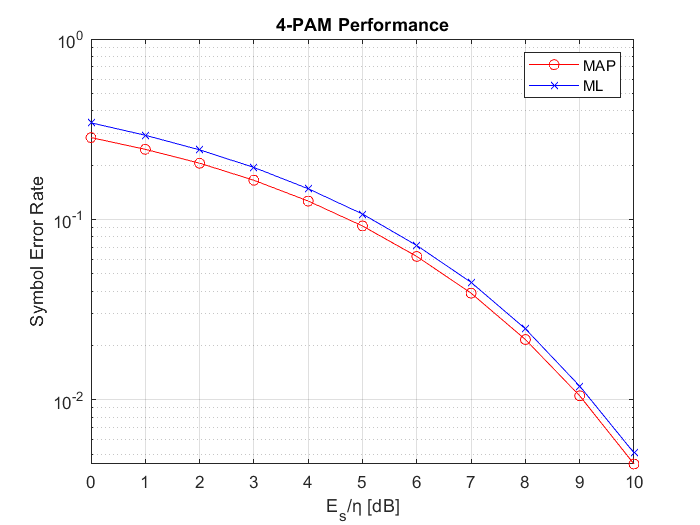

semilogy(snr_db,Pe_MAP,'ro-');hold on;grid on;
semilogy(snr_db,Pe_ML,'bx-');
xlabel('E_s/η [dB]');
ylabel('Symbol Error Rate');
title('4-PAM Performance');
legend('MAP','ML');

As it can be observed by employing MAP receiver error probability

is always lower than the situation in which ML receiver is employed.

In addition it can be deduced that by increment of SNR, error probabilty

decreases. The graph is shown in the result bar.

### -----------------------------------------------------------------

### Local Functions:

function [p,t] = RCP(sampling_error,beta)
              %%Raised Cosine Pulses
    T=1;
    Fs=10;
    dt=T/Fs;
        %% epsilon=0
    if sampling_error == 0
        t=(-6*T:dt:6*T)-sampling_error;
        ind1 = find(t==T/(2*beta));
        ind2 = find(t==-T/(2*beta));
    end
        %% epsilon=0.1T
    if sampling_error == 0.1*T
        t=(-6*T:dt:6*T)-sampling_error;
        ind1 = find(abs(t-T/(2*beta))<0.0001);
        ind2 = find(abs(t+T/(2*beta))<0.0001);
    end
        %% epsilon=0.2T
    if sampling_error == 0.2*T
        t=(-6*T:dt:6*T)-sampling_error;
        ind1 = find(abs(t-T/(2*beta))<0.0001);
        ind2 = find(abs(t+T/(2*beta))<0.0001);
    end
    
    p=zeros(1,length(t));
    for i=1:length(t)
        if i==ind1
              p(i) = pi/4 * sinc(1/(2*beta));
        elseif i==ind2
              p(i) = pi/4 * sinc(1/(2*beta));
        else
              p(i) = sinc(t(i)/T).*(cos(pi*beta*t(i)/T)/(1-(2*beta*t(i)/T).^2));
        end
    end
end

function symb = detect_symbols(samples,thresholds)
    th1 = thresholds(1);
    th2 = thresholds(2);
    th3 = thresholds(3);
    symb = samples;
    symb(symb < th1) = -3;
    symb(symb > th1 & symb < th2) = -1;
    symb(symb > th2 & symb < th3) = 1;
    symb(symb > th3) = 3;
end